% 参考文献：Spectral Approach in Vibrations of Overhead Transmission Lines
% 目的：文章结果复现
% 状态：成功
% ================================================

## 参数设置

clear;clc

% 材料参数
material.E = 74e9;       % 索的弹性模量 (Pa)
material.ita = 0.01;       % 阻尼

material.rho = 2700;       % 索的密度 (kg/m³)
material.A = 50e-6;       % 索的截面积 (m2)
material.m = material.rho * material.A;        % 索的每延米质量 (kg/m)
material.D = sqrt(4 * material.A / pi());    % 索的直径 (m)

material.L = 100;        % 索的长度 (m)
material.T = 10000;         % 索的张力 (N)
material.I = pi * material.D^4 / 64;  % 索的惯性矩 (m⁴)

material.EI = material.E *material.I;

% 单元划分
n_elements = 3;  % 3个单元
element_length = material.L / n_elements;  % 每个单元长度


## 计算和结果

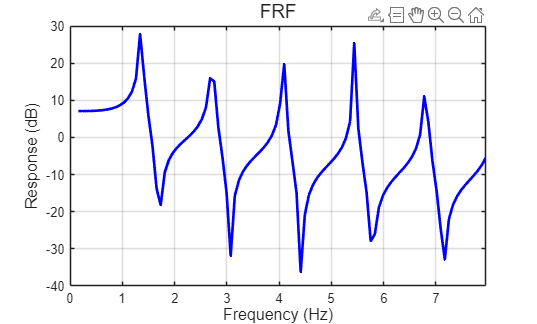

omega_values = linspace(1, 50, 100);
fre = omega_values ./ (2*pi());
H_values = zeros(size(omega_values));

for i = 1:length(omega_values)
    omega = omega_values(i);

    % 初始化全局矩阵 (4节点，每个节点有2个自由度)
    global_dof = 2*(n_elements+1);
    K_global = zeros(global_dof, global_dof);
    
    % 组装每个单元的矩阵
    for elem = 1:n_elements
        % 获取单元局部矩阵
        S_local = spetral_element_matrix(omega, material, element_length);
        
        % 计算全局自由度索引
        start_dof = 2*(elem-1)+1;
        end_dof = start_dof + 3;
        
        % 组装到全局矩阵
        K_global(start_dof:end_dof, start_dof:end_dof) = ...
            K_global(start_dof:end_dof, start_dof:end_dof) + S_local;
    end

    % 应用边界条件 (两端简支)
    % 固定第一个节点的位移和最后一个节点的位移
    fixed_dofs = [1, 2*(n_elements+1)-1];
    free_dofs = setdiff(1:global_dof, fixed_dofs);
    
    % 提取自由度的子矩阵
    K_reduced = K_global(free_dofs, free_dofs);

    % 计算频响函数 (选择中间节点的横向位移)
    % 中间节点是第2个节点 (对于3个单元)
    response_dof = 2;  % 第二个节点的横向位移自由度
    % 找到响应自由度在缩减系统中的位置
    response_idx = find(free_dofs == response_dof);    

    if ~isempty(response_idx)
        inv_K = inv(K_reduced);
        H = inv_K(response_idx, response_idx);
        H_values(i) = 20 * log10(abs(H));
    else
        H_values(i) = -Inf;  % 如果响应自由度被约束
    end
end



% 理论解计算(前5阶固有频率)
n_modes = 6;             % 计算模态数
omega_b = zeros(1,n_modes);
for n = 1:n_modes
    omega_b(n) = (pi()^2 / material.L^2) * sqrt(material.EI/material.m) * ...
                 sqrt(n^4 + n^2 * material.T * material.L^2 / (pi()^2 * material.EI));
end
f_theory = omega_b/(2*pi()); % 转换为Hz


% 绘制频响函数
plot_FRF(fre, H_values, f_theory);

*% ============== 函数定义 ==============*

function [s11, s12, s13, s14, s22, s23, s24] = calculate_matrix_elements(k, L)
    s11 = -k.^3 .* (cos(k*L).*sinh(k*L) + sin(k*L).*cosh(k*L));
    s12 = -k.^2 .* sin(k*L) .* sinh(k*L);
    s13 = k.^3 .* (sin(k*L) + sinh(k*L));
    s14 = k.^2 .* (cos(k*L) - cosh(k*L));
    s22 = k .* (cos(k*L).*sinh(k*L) - sin(k*L).*cosh(k*L));
    s23 = k.^2 .* (cosh(k*L) - cos(k*L));
    s24 = k .* (sin(k*L) - sinh(k*L));
    % s33等于s11
    % s34等于-s12
    % s44等于s22
end

% 谱元矩阵函数
function S = spetral_element_matrix(omega, material, L)
    % 计算波数 k (公式5)
    alpha = material.T / (2 * material.EI);
    beta = material.m / material.EI;
    % 计算波数
    k = sqrt(sqrt(alpha^2 + beta * omega^2) - alpha);
    
    % 计算矩阵元素
    [s11, s12, s13, s14, s22, s23, s24] = calculate_matrix_elements(k, L);
   
    % 计算Delta
    delta = cos(k*L) .* cosh(k*L) - 1;
    
    % 构建对称矩阵
    S = material.EI ./ delta .* [ ...
        s11,  s12,  s13,  s14; ...
        s12,  s22,  s23,  s24; ...
        s13,  s23,  s11, -s12; ...  % s33 = s11, s34 = -s12
        s14,  s24, -s12,  s22  ...  % s44 = s22
    ];
end

function plot_FRF(fre, H_values,f_theory)
    figure;
    plot(fre, H_values, 'b-', 'LineWidth', 2);

    xlabel('Frequency (Hz)', 'FontSize', 12);
    ylabel('Response (dB)', 'FontSize', 12);
    title(sprintf('FRF'), ...
        'FontSize', 14);
    grid on;
    xlim([0 max(fre)]);
end